# Examples - Triangle Theory

Determine SMB operating conditions and plot the triangular separation region according to theTriangle Theory framework.

clear; clc;

% Column info for all examples
Lc = 10;  % column length
Dc = 2.1;  % column diameter
epsb = 0.4;  % porosity
Q1 = 15;  % SMB flow rate in zone I

## Linear isotherm

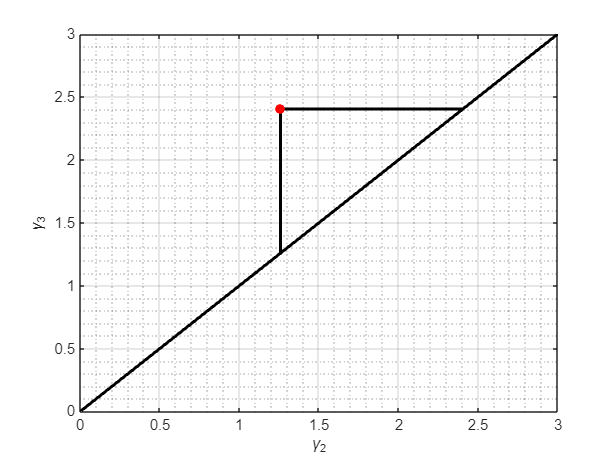

H = [0.8386 1.6034];  % linear isotherm constants

figure()
[flowrates, tsw] = triangleTheory.linear(Lc, Dc, epsb, H, Q1);

% Flowrates as a structure
flowrates

flowrates = struct with fields:
    QE: 5.0536
    QX: 5.0536
    QF: 5.0536
    QR: 5.0536
    Q1: 15.0000
    Q2: 9.9464
    Q3: 15.0000
    Q4: 9.9464


% And the switch time
tsw

tsw = 3.1450

Now lets select a safety factor and an operating point inside the triangle.

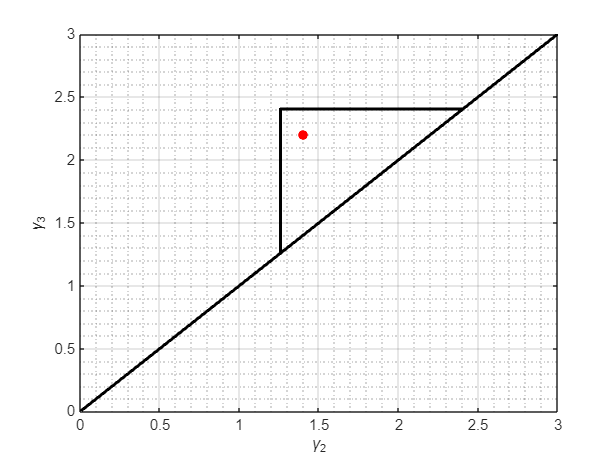

beta = 1.2;  % safety factor
gamma23 = [1.4, 2.2];  % operating point inside triangle

figure()
[flowrates, tsw, r] = triangleTheory.linear(Lc, Dc, epsb, H, Q1, beta, gamma23);

% We can get all the data from the r output
r

r = struct with fields:
           QE: 7.0940
           QX: 5.7363
           QF: 3.0879
           QR: 4.4456
           Q1: 15.0000
           Q2: 9.2637
           Q3: 12.3517
           Q4: 7.9060
          tsw: 3.5893
    gamma_TMB: [2.8861 1.4000 2.2000 1.0482]
    gamma_SMB: [3.8861 2.4000 3.2000 2.0482]
            m: [1.9241 0.9333 1.4667 0.6988]
           Vc: 34.6361


We can also plot the gamma1-gamma4 region in the same plot.

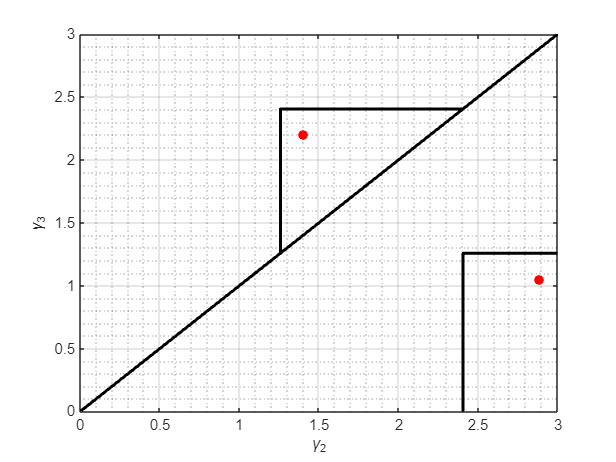

figure()
[flowrates, tsw] = triangleTheory.linear(Lc, Dc, epsb, H, Q1, beta, gamma23, true, true);

## Langmuir isotherm

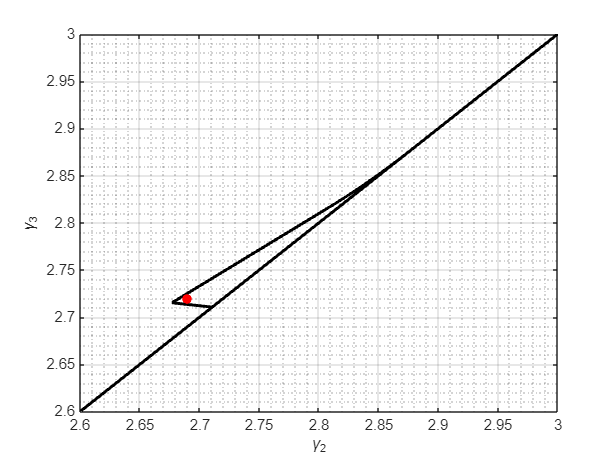

Q = [17.544	17.606];  % Langmuir isotherm constant Q (capacity)
b = [0.103	0.109];  % Langmuir isotherm constant b (b1 < b2)
Cfeed = [1.5 0.5];  % feed concentration
beta = 1.2;

% Select an operation point
gamma23 = [2.69, 2.72];

figure()
[flowrates, tsw, r] = triangleTheory.langmuir(Lc, Dc, epsb, Q, b, Cfeed, Q1, beta, gamma23);

% All data available in the data field as a structure
r

r = struct with fields:
           QE: 4.0259
           QX: 2.5738
           QF: 0.1010
           QR: 1.5531
           Q1: 15
           Q2: 12.4262
           Q3: 12.5272
           Q4: 10.9741
          tsw: 4.1141
    gamma_TMB: [3.4543 2.6900 2.7200 2.2588]
    gamma_SMB: [4.4543 3.6900 3.7200 3.2588]
            m: [2.3029 1.7933 1.8133 1.5059]
           Vc: 34.6361


## Linear-Langmuir isotherm

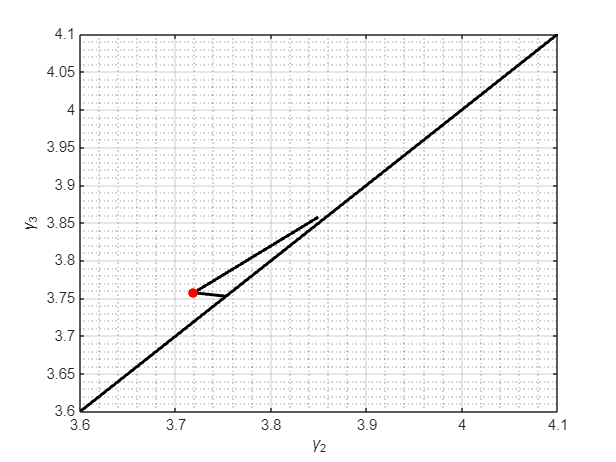

m = 0.6947;  % Linear isotherm term constant m
Q = [17.544	17.606];  % Langmuir isotherm constant Q (capacity)
b = [0.103	0.109];  % Langmuir isotherm constant b (b1 < b2)
Cfeed = [1.5 0.5];  % feed concentration
beta = 1.2;

figure()
[flowrates, tsw, r] = triangleTheory.linearLangmuir(Lc, Dc, epsb, m, Q, b, Cfeed, Q1, beta);